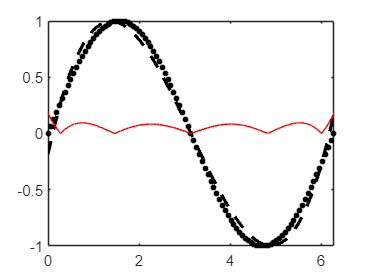

clear all;
close all;
clc;

%generat sample signal
nt = 101;
t= linspace(0,2*pi,nt);
f= sin(t);

t2= linspace(0,4*pi,nt);
f2= sin(t2);

%polyfit reconstruction coefficients
degree = 3;
degree2 = 3;
coef_rec=polyfit(t,f,degree);
coef_rec2=polyfit(t2,f2,degree2);

%t range
nt_rec=1001;
t_fit=linspace(min(t),max(t),nt_rec);
t2_fit=linspace(min(t2),max(t2),nt_rec);

%polynomial values
f_rec=polyval(coef_rec,t_fit);
f2_rec=polyval(coef_rec2,t2_fit);

%error
f_ana=interp1(t,f,t_fit);
err=abs(f_rec-f_ana);

f2_ana=interp1(t2,f2,t2_fit);
err2=abs(f2_rec-f2_ana);

%plot
figure(1)
plot(t,f,'ko','MarkerSize',3,'MarkerFaceColor','k')
hold on
plot(t_fit,f_rec,'--k','LineWidth',2)
hold on
plot(t_fit,err,'-r')
hold on
xlim([0,max(t)])

hold off

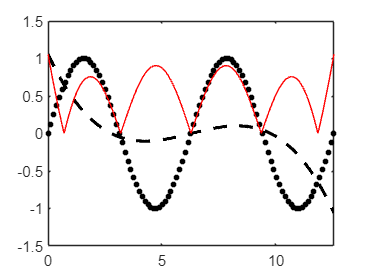


figure(2)
plot(t2,f2,'ko','MarkerSize',3,'MarkerFaceColor','k')
hold on
plot(t2_fit,f2_rec,'--k','LineWidth',2)
hold on
plot(t2_fit,err2,'-r')
hold on
xlim([0,max(t2)])